# Lower bound on number of tropical limit cycles

Script to draw the phase portrait of a tropical dynamical system of arbitrary degree $n$ with $\frac{1}{2}\,(n-2)\,(n-3)$ limit cycles.

## Parameters

clear
close all
N = 5; % Degree of the system. N >= 4
l1 = 2; % Length of manifold with slope 1
l2 = 4; % Length of manifold with slope 1/2
l3 = 6; % Length of manifold with slope 0


## Determine Tropical Polynomials

M = [1 0; 1 1; 0 2];
m = 3;
nM = 3;
while m < N
    nM = nM+1;
    M(nM,:) = [0 m];
    nM = nM+1;
    M(nM,:) = [1 m-1];
    m = m+1;
end
for n = 2:N-4
    m = 0;
    while n+m<N
        nM = nM+1;
        M(nM,:) = [n m];
        m = m+1;
    end
end
n = N-3;
for m = 0:1
    nM = nM+1;
    M(nM,:) = [n m];
end
U = zeros(N);
V = zeros(N);
B = zeros(N);
nG = size(M,1);
G = zeros(nG, 4);
G(:,3:4) = M;
for k = 1:nG
    if mod(M(k,2), 2) == 0
        G(k,1) = 1;
    else
        G(k,1) = -1;
    end
end
for k = 4:nG
    nk = M(k,1);
    mk = M(k,2);
    if mk == 0
        n1 = nk-1;
        n2 = nk-1;
        m1 = 1;
        m2 = 2;
    elseif nk == 0
        n1 = nk;
        n2 = nk + 1;
        m1 = mk - 1;
        m2 = mk - 2;
    else
        n1 = nk;
        n2 = nk - 1;
        m1 = mk - 1;
        m2 = mk + 1;
    end
    c = abs((n2-n1)/(m2-m1));
    if nk > 1 && mk ~= 0
        uk = U(n1+1, m1+1);
        if mk > 1
            uk = l1 + uk;
        end
    else
        uk = U(n2+1, m2+1);
    end
    if c == 1
        uk = uk + l1;
    elseif c == 0
        uk = uk + l3;
    else
        uk = uk + l2;
    end
    U(nk+1, mk+1) = uk;
    b1 = B(n1+1, m1+1);
    b2 = B(n2+1, m2+1);
    bk = -((m1-m2)*nk*uk + (m2-mk)*(n1*uk+b1) + (mk-m1)*(n2*uk+b2))/(m1-m2);
    G(k,2) = bk;
    B(nk+1, mk+1) = bk;
    V(nk+1, mk+1) = -((n1-n2)*uk+b1-b2)/(m1-m2);
end
du = -(l3-l1)/2;
dv = l1/2;
F = G;
F(:,2) = G(:,2) - du*G(:,3) - dv*G(:,4) - max(- du*G(:,3) - dv*G(:,4)) - 1;
F(:,1) = -F(:,1);


## Draw Tropical Phase Portrait

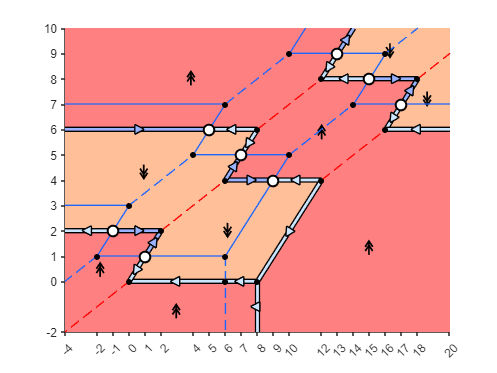

close all
figure
ulim = [-2*l1 2*l1+max(U,[],'all')];
vlim = [-l1 l1+max(V,[],'all')];
h = TropicalPhasePlane(F,G,ulim,vlim);